# 智能优化算法：樽海鞘优化算法求解函数极小值

算法下载：[https://au.mathworks.com/matlabcentral/fileexchange/63745-ssa-salp-swarm-algorithm](https://au.mathworks.com/matlabcentral/fileexchange/63745-ssa-salp-swarm-algorithm)

clear;clc;
% 搜索数量
SearchAgents_no = 30;
% 最大迭代次数
Max_iter = 200;
% 变量维度
dim = 2;
% 上限
ub = 10 * ones(1, dim);
% 下限
lb = -10 * ones(1, dim);
% 初始化位置
Positions = rand(SearchAgents_no, dim) .* repmat(ub - lb, SearchAgents_no, 1) + repmat(lb, SearchAgents_no, 1); 
Convergence_curve = zeros(1, Max_iter);
SalpFitness = nan(1, Max_iter);
Sorted_salps = nan(SearchAgents_no, dim);
% 计算适应度值
for i = 1 : SearchAgents_no
    SalpFitness(1, i) = ObjFun(Positions(i, :));
end
[sorted_salps_fitness, sorted_indexes] = sort(SalpFitness);
for i = 1:SearchAgents_no
    Sorted_salps(i, :) = Positions(sorted_indexes(i), :);
end
FoodPosition = Sorted_salps(1, :);
FoodFitness = sorted_salps_fitness(1);
Convergence_curve(1) = FoodFitness;
% 主循环
for l = 2:Max_iter
    c1 = 2*exp(-(4*l/Max_iter)^2);    
    for i = 1:SearchAgents_no
        SalpPositions = Positions';      
        if i <= SearchAgents_no/2
            for j = 1:dim
                c2 = rand();
                c3 = rand();
                if c3 < 0.5 
                    SalpPositions(j, i) = FoodPosition(j) + c1*((ub(j) - lb(j))*c2 + lb(j));
                else
                    SalpPositions(j, i) = FoodPosition(j) - c1*((ub(j) - lb(j))*c2 + lb(j));
                end
            end  
        elseif i > SearchAgents_no/2
            point1 = SalpPositions(: , i-1);
            point2 = SalpPositions(: , i);
            SalpPositions(:, i) = (point2 + point1) / 2;
        end
        Positions= SalpPositions';
    end
    % 更新
    for i = 1:SearchAgents_no
        % 边界处理：越界赋值为边界值
        Flag4ub = Positions(i, :) > ub;
        Flag4lb = Positions(i, :) < lb;
        Positions(i, :) = (Positions(i, :).*(~(Flag4ub + Flag4lb))) + ub.*Flag4ub + lb.*Flag4lb;        
        SalpFitness(i) = ObjFun(Positions(i, :));
        if SalpFitness(i) < FoodFitness
            FoodPosition = Positions(i, :);
            FoodFitness = SalpFitness(i);
        end
    end    
    Convergence_curve(l) = FoodFitness;
end
disp(['最优值：' num2str(FoodPosition)]);

最优值：1.7804e-07 -3.3985e-07


disp(['最优值对应目标函数：' num2str(FoodFitness)]);

最优值对应目标函数：1.4744e-13


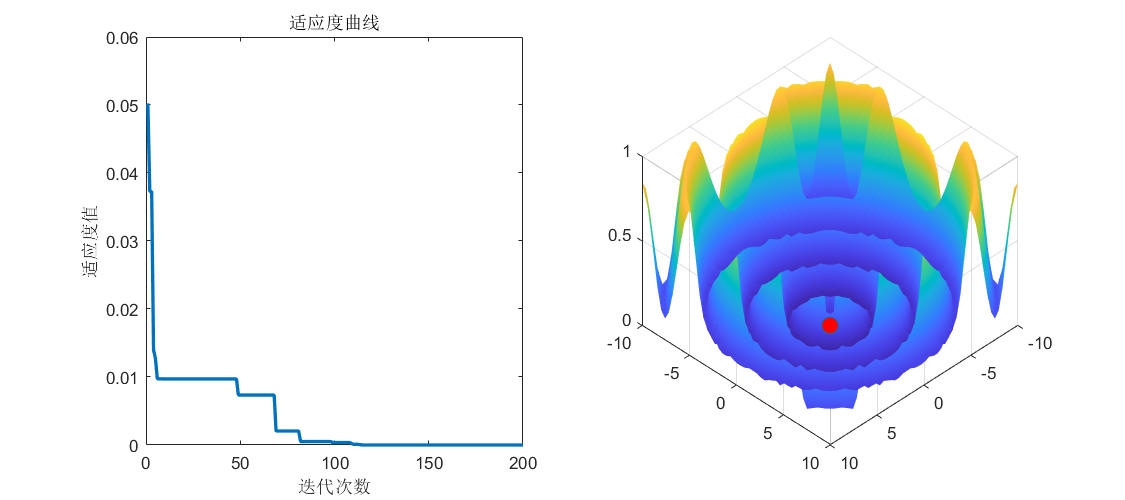

subplot(1, 2, 1)
plot(Convergence_curve, 'LineWidth', 2);
xlabel('迭代次数');
ylabel('适应度值');
title('适应度曲线');
len = 50;
xRange = linspace(lb(1), ub(1), len);
yRange = linspace(lb(2), ub(2), len);
[xMap, yMap] = meshgrid(xRange, yRange);
zMap = zeros(len);
for i = 1 : len
    for j = 1 : len
        zMap(i, j) = ObjFun([xMap(i, j), yMap(i, j)]);
    end
end
subplot(1, 2, 2)
surf(xRange, yRange, zMap);
view(-45, -45);
shading interp
hold on
plot3(FoodPosition(1), FoodPosition(2), FoodFitness, 'o', 'MarkerFaceColor', 'r', 'MarkerSize', 10);
hold off
set(gcf, 'Position', [400, 200, 900, 400]);

function result = ObjFun(x)
x1 = x(1);
x2 = x(2);
t = x1^2 + x2^2;
result = 0.5 + (sin(sqrt(t))^2 - 0.5) / (1 + 0.001 * t)^2;
end